# Import data from spreadsheet

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 05-May-2021 00:16:36

## Set up the Import Options and import the data

opts = spreadsheetImportOptions("NumVariables", 3);

% Specify sheet and range
opts.Sheet = "exp_2";
opts.DataRange = "A2:C47";

% Specify column names and types
opts.VariableNames = ["f", "L", "start"];
opts.VariableTypes = ["double", "double", "double"];

% Import the data
dataS1 = readtable("C:\физика\2.1.3\data.xlsx", opts, "UseExcel", false)

dataS1 = 46×3 table
      f        L     start
    ______    ___    _____

     702.3     27      1  
       702    218      0  
     701.9    217     -1  
     701.8     28      0  
    1405.4     80      1  
      1405    178      0  
    1404.8    176     -1  
    1404.7     81      0  
    2099.7      6      1  
    2099.4     70      0  
    2099.3    135      0  
    2099.2    198      0  
    2099.1    199     -1  
      2099    134      0  
      2099     70      0  
      2099      6      0  


## Clear temporary variables

clear opts

hold on;
grid on;
y_1 = dataS1.L(1:4) - dataS1.L(1);
y_2 = dataS1.L(5:8) - dataS1.L(5);
y_3 = dataS1.L(9:16) - dataS1.L(9);
y_4 = dataS1.L(17:26)- dataS1.L(17);
y_5 = dataS1.L(27:38) - dataS1.L(27);
y_6 = dataS1.L(39:46) - dataS1.L(39);
x_1_2 = [1;2;2;1];
x_3 = [1;2;3;4;4;3;2;1];
x_4 = [1;2;3;4;5;5;4;3;2;1];
x_5 = [1;2;3;4;5;6;6;5;4;3;2;1];

xlim([1,6]);
ylim([0,200]);
point_1 = scatter(x_1_2,y_1);
coeff_1 = polyfit(x_1_2,y_1, 1)

coeff_1 =   190.0000 -189.5000


y1 = 0;
xi = min(0):0.1:max(6);
for k=0:1
    y1 = y1 + coeff_1(1-k+1) * xi.^k;
end
gr_1 = plot(xi, y1); 

point_2 = scatter(x_1_2,y_2);
coeff_2 = polyfit(x_1_2,y_2, 1)

coeff_2 =    96.5000  -96.0000


y1 = 0;
xi = min(0):0.1:max(6);
for k=0:1
    y1 = y1 + coeff_2(1-k+1) * xi.^k;
end
gr_2 = plot(xi, y1);

point_3 = scatter(x_3,y_3);
coeff_3 = polyfit(x_3,y_3, 1)

coeff_3 =    64.2000  -64.2500


y1 = 0;
xi = min(0):0.1:max(6);
for k=0:1
    y1 = y1 + coeff_3(1-k+1) * xi.^k;
end
gr_3 = plot(xi, y1);

point_4 = scatter(x_4,y_4);
coeff_4 = polyfit(x_4,y_4, 1)

coeff_4 =    48.1000  -48.2000


y1 = 0;
xi = min(0):0.1:max(6);
for k=0:1
    y1 = y1 + coeff_4(1-k+1) * xi.^k;
end
gr_4 = plot(xi, y1);

point_5 = scatter(x_5,y_5);
coeff_5 = polyfit(x_5,y_5, 1)

coeff_5 =    38.7429  -39.1000


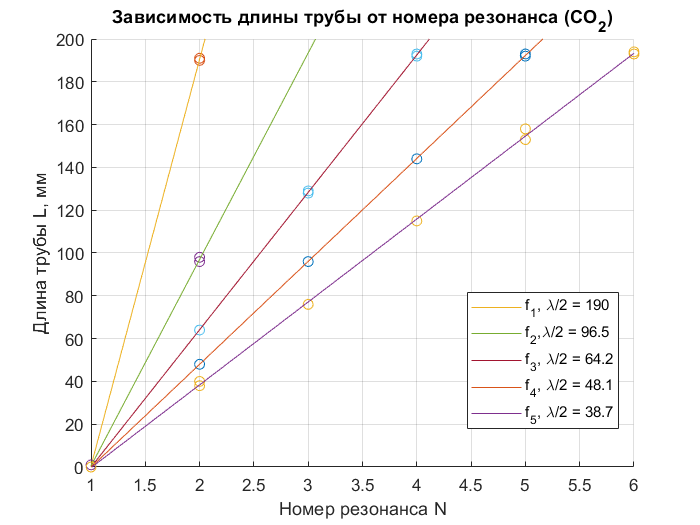

y1 = 0;
xi = min(0):0.1:max(6);
for k=0:1
    y1 = y1 + coeff_5(1-k+1) * xi.^k;
end
gr_5 = plot(xi, y1);

title("Зависимость длины трубы от номера резонанса (CO_2)")
xlabel('Номер резонанса N')
ylabel('Длина трубы L, мм')
legend([gr_1, gr_2, gr_3, gr_4, gr_5], {'f_1, \lambda/2 = 190', 'f_2,\lambda/2 = 96.5', 'f_3, \lambda/2 = 64.2', 'f_4, \lambda/2 = 48.1', 'f_5, \lambda/2 = 38.7'}, 'Location','best')
hold off;